16 Element array array space half awavelength apart

function H = create_mat(n,theta)
    H = zeros(n);
    for ii = 1:n
        for jj = 1:n
            for aa = 1:numel(theta)
                H(ii,jj) = H(ii,jj) + exp(1j*2*pi*(ii-jj)*theta(aa));
            end
        end
    end
end

n = 16;
thetaT = deg2rad([-10]);
thetaT = .5*sin(thetaT);
thetaC = deg2rad([11 12 35 36]);
thetaC = .5*sin(thetaC);
 
HT = create_mat(n,thetaT);
HC = create_mat(n,thetaC);

HC = HC(1:numel(thetaC),:);
HT = HT(1:numel(thetaT),:);

P = eye(n) - HC'*inv(HC*HC')*HC;

[vecs,vals] = eig(P'*(HT'*HT)*P);
diag(vals)

ans =   -0.0000 - 0.0000i
  15.2019 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
  -0.0000 - 0.0000i
  -0.0000 + 0.0000i
   0.0000 + 0.0000i
   0.0000 + 0.0000i


[maxval,idx] = max(diag(vals))

maxval = 15.2019 + 0.0000i

idx = 2

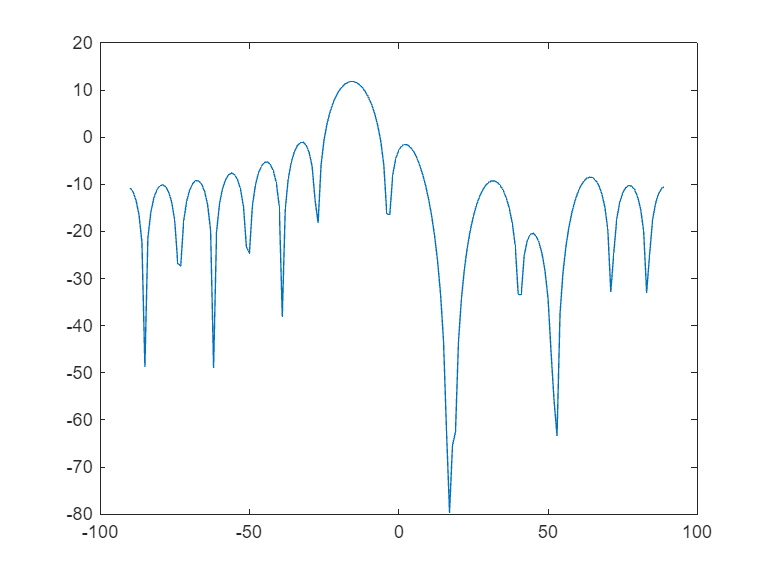

BF = vecs(:,idx);
nfft = 180;
x = -nfft/2:(nfft/2-1);
figure; plot(x,mag2db(abs(fftshift(fft(BF,nfft)))))

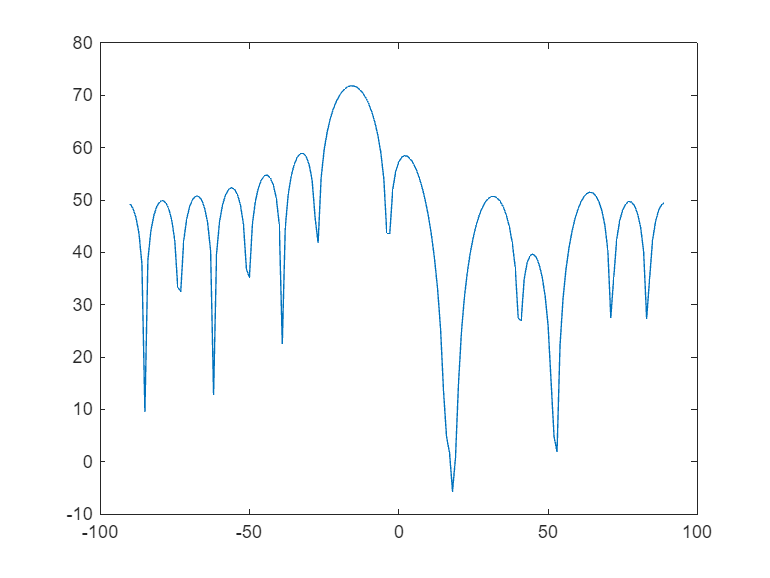

[vecs,vals] = eig((HT'*HT),HC'*HC+.000001*eye(n));
[~,idx] = max(diag(vals));
BF = vecs(:,idx);
nfft = 180;
x = -nfft/2:(nfft/2-1);
figure; plot(x,mag2db(abs(fftshift(fft(BF,nfft)))))